Esempio 1

$f(x)=x^2-2$ in $[1\ 2]$

f=@(x) x.^2-2;
df=@(x) 2*x;
x0=1.5;
tol=1e-8;
nitmax=10;
[x,nit,fx]=newton(f,df,x0,tol,nitmax);
format longe

Esercizio 2

Calcolare le prime 10 cifre significative dell'unico zero positivo di $f(x)=x^6-x-1
$. Fornire una approssimazione iniziale che abbia almeno 2 cifre corrette.

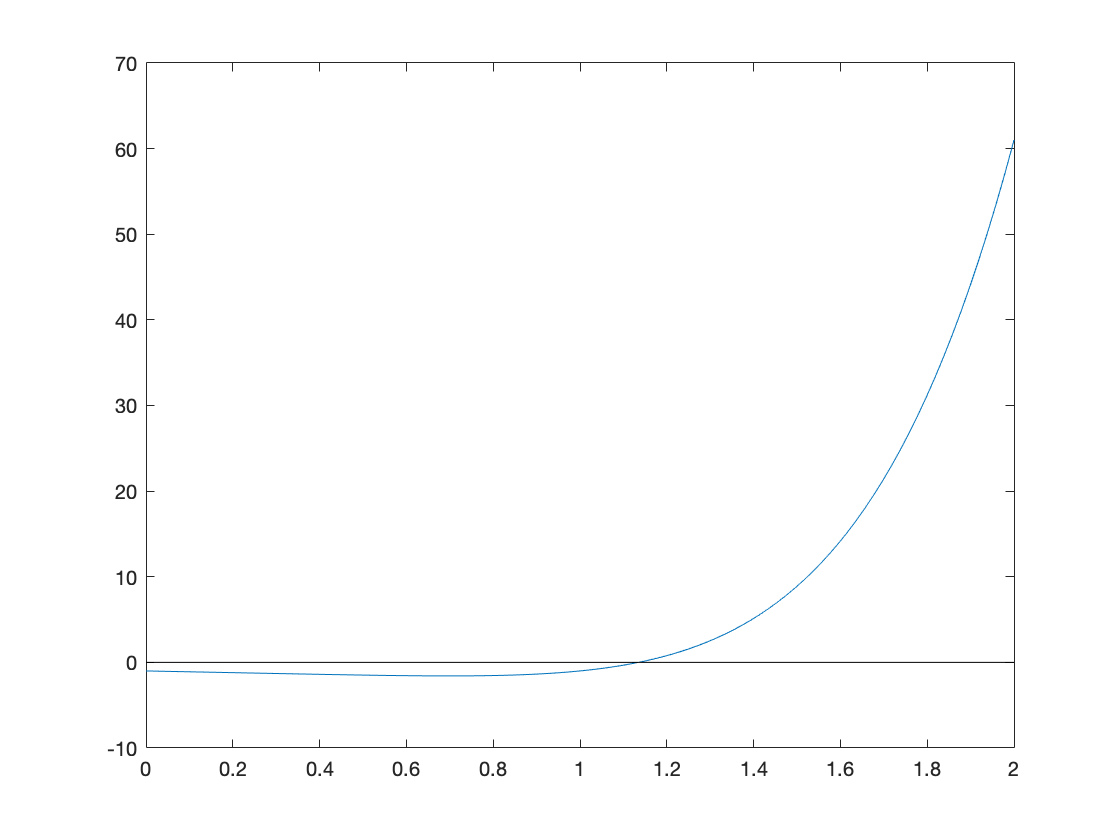

f=@(x) x.^6-x-1;
x_mesh=linspace(0,2);
plot(x_mesh,f(x_mesh)) % grafico della funzione
hold on
plot([0 2],[0 0],'k') % asse delle ascisse

x0=1.1;
% x0=(1/6)^(1/5);
df=@(x) 6*x.^5-1;
tol=1e-7;
nitmax=10;
restoredefaultpath
[x,nit,res]=newton_extra(f,df,x0,tol,nitmax);

0	 1.100000000000000	 -3.3e-01
1	 1.137912585160440	 +3.3e-02
2	 1.134748520270514	 +2.5e-04
3	 1.134724139838480	 +1.5e-08
4	 1.134724138401519	 -8.9e-16


Esempio 2

Mostriamo graficamente l'ordine di convergenza esibito dall'esercizio precedente.

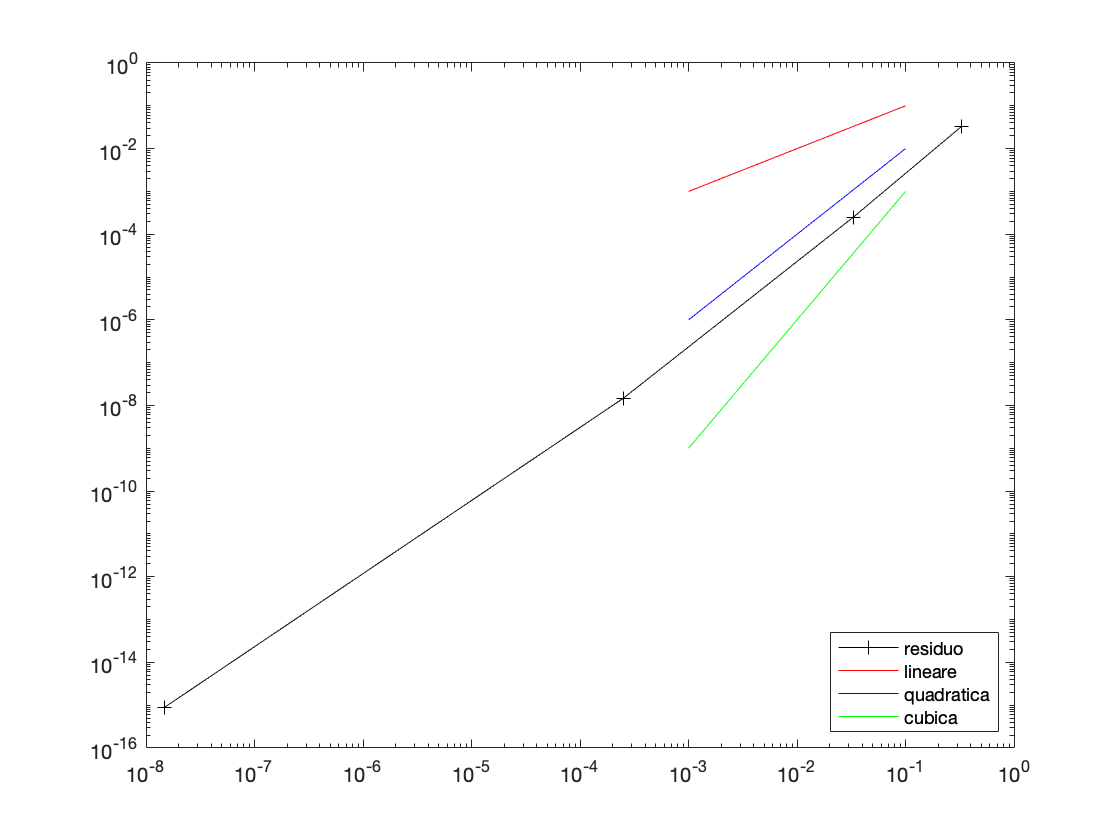

figure
loglog(abs(res(1:end-1)),abs(res(2:end)),'+-k')
hold on
loglog([1e-1 1e-3],[1e-1 1e-3],'r') % convergenza lineare
loglog([1e-1 1e-3],[1e-2 1e-6],'b') % convergenza quadratica
loglog([1e-1 1e-3],[1e-3 1e-9],'g') % convergenza cubica
legend('residuo','lineare','quadratica','cubica','location','southeast')